# Project Team 12 - Data Analysis - Data Driven Marketing

**Thành viên trong nhóm:**

- Bùi Thị Ánh Hương - 19000263 

- Lê Ngọc Yến Nhi - 19000283

- Nguyễn Thanh Mai - 19000357

- Đặng Quang Anh - 19000243

## BÀI TOÁN MARKETING

- Marketing là gì ? 

Có rất nhiều định nghĩa về marketing, tuy nhiên trong bài viết của nhóm em xin đề cập đến định nghĩa marketing của *Philip Kotler *– Cha đẻ của ngành Marketing hiện đại. " Marketing là nghệ thuật tạo ra giá trị, truyền thông và phân phối những giá trị đó nhằm thỏa mãn vấn đề của khách hàng mục tiêu để đem lại lợi nhuận tối ưu của doanh nghiệp ". Hay hiểu một cách đơn giản marketing là tiếp thị. Trong quá trình phát triển của marketing, ban đầu chỉ áp dụng cho các doanh nghiệp sản xuất hàng hóa tiêu dùng, sau đó dần dần marketing phát triển và áp dụng trong sản xuất công nghiệp, các ngành dịch vụ và phi thương mại. Sau đó, marketing tiếp tục xâm nhập vào tất cả các lĩnh vực kinh doanh như sức khỏe, chính trị, văn hóa, xã hội,... và trở thành một hoạt động không thể thiếu trong quá trình kinh doanh của các cá nhân và doanh nghiệp.

- Lịch sử phát triển của Marketing

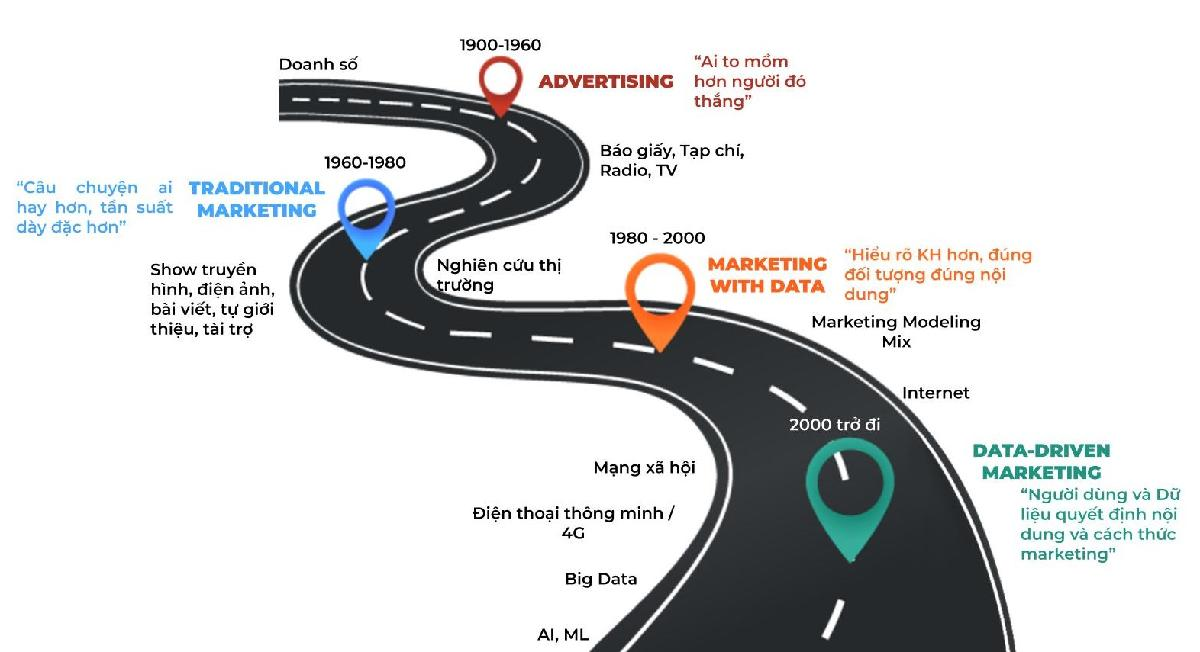

- Sự phai mờ của marketing truyền thống

Cách đây khoảng 10 năm, khi Internet chưa thực sự phát triển như bây giờ thì hình thức marketing truyền thống rất phổ biến. Mọi người có thể dễ dàng nhìn thấy nó trong cuộc sống như: phát tờ rơi, tổ chức hội thảo, quảng cáo truyền hình, tài trợ cho sự kiện, chương trình, In ấn catalogue, triển lãm thương mại, hội chợ. Tuy nhiên điểm yếu có thể coi là lớn nhất của các phương pháp truyền thống này đó là chi phí cao và tốn thời gian. Khi mà các doanh nghiệp hướng đến các hình thức marketing tiết kiệm chi phí và tối đa lợi nhuận thì cũng là lúc digital marketing đang dần chiếm sóng của traditional marketing. Các công cụ chính của digital marketing ngày nay có thể thể đến SEO, Content Marketing, Social Marketing, Pay Per Click, Affiliate Marketing, Native Advertising, Marketing Automation, Email Marketing,... ví dụ đơn giản nhất cho hình thức digital marketing đó là những tin nhắn quảng cáo về messenger hoặc gmail. Vậy bạn đã bao giờ thắc mắc rằng tại sao mình lại nhận được tin nhắn quảng cáo đó mà không phải là ai khác ? Điều gì làm cho các marketer của công ty biết được đến nhu cầu của mình ? Để trả lời cho các câu hỏi đó chúng ta chuyển sang Data Driven Marketing.

- Tại sao dữ liệu lại ảnh hướng lớn đến marketing ngày nay ? 

Data-Driven Marketing là thời đại mà **người dùng và dữ liệu** quyết định nội dung và cách thức Marketing. Hoạt động được triển khai dựa trên việc tổng hợp và phân tích các dữ liệu. Từ những dữ liệu này, marketers phân tích và chắt lọc ra những nhu cầu, xu hướng, hành vi, insight thầm kín… của khách hàng. Đồng thời chúng hỗ trợ doanh nghiệp tiếp cận với đối tượng mục tiêu dễ dàng hơn. Chính vì thế mà dữ liệu tốt có thể không giúp doanh nghiệp của bạn thành công ngay nhưng nếu bạn muốn doanh nghiệp thành công thì data là nhân tố quan trọng rất đáng để đầu tư. Hiểu được tầm quan trong của data trong marketing, trong đề tài lần này của nhóm em đã sử dụng các kỹ thuật phân tích dữ liệu và kiểm định thống kê bằng Matlab để tìm ra insight khách hàng.

## XỬ LÝ DỮ LIỆU

### **Tải Dữ Liệu**

File dữ liệu là kết quả thu nhập khảo sát khách hàng của một công ty thực phẩm phân phối sản phẩm tại nhiều nước. Dữ liệu bao gồm:

- Các thông tin cơ bản của khách hàng(về trình độ, thu nhập, ngày đăng ký, tình trạng hôn nhân) 

- Thống kê số lần mua bán của mỗi khách hàng qua các kênh bán hàng của công ty(online, offline). 

-  Khảo sát khách hàng đối với các chiến dịch marketing của công ty qua đó để phân tích thị khiếu của người tiêu dùng tại mỗi nơi. 

% import file marketingdata
marketingdata = importfile('marketingdata.csv', 2, 2241);
% import file marketingdata theo column
[ID,Year_Birth,Education,Marital_Status,Income,Kidhome,Teenhome,Dt_Customer,Recency,MntWines,MntFruits,MntMeatProducts,MntFishProducts,MntSweetProducts,MntGoldProds,NumDealsPurchases,NumWebPurchases,NumCatalogPurchases,NumStorePurchases,NumWebVisitsMonth,AcceptedCmp3,AcceptedCmp4,AcceptedCmp5,AcceptedCmp1,AcceptedCmp2,Response,Complain,Country] = importfile1('marketingdata.csv',2, 2241);
% print data
disp(marketingdata);

     ID      Year_Birth      Education       Marital_Status      Income      Kidhome    Teenhome    Dt_Customer    Recency    MntWines    MntFruits    MntMeatProducts    MntFishProducts    MntSweetProducts    MntGoldProds    NumDealsPurchases    NumWebPurchases    NumCatalogPurchases    NumStorePurchases    NumWebVisitsMonth    AcceptedCmp3    AcceptedCmp4    AcceptedCmp5    AcceptedCmp1    AcceptedCmp2    Response    Complain    Country
    _____    __________    _____________

% shape of data
[row, column] = size(marketingdata);
fprintf('shape of data');

shape of data

disp([row, column]);

  Column 1

        2240

  Column 2

          28



properties = marketingdata.Properties;
disp(properties);

  TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {1×28 cell}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.



%finding missing values in columns
total = sum(ismissing(marketingdata));
disp(total);

  Column 1

     0

  Column 2

     0

  Column 3

     0

  Column 4

     0

  Column 5

    24

  Column 6

     0

  Column 7

     0

  Column 8

     0

  Column 9

     0

  Column 10

     0

  Column 11

     0

  Column 12

     0

  Column 13

     0

  Column 14

     0

  Column 15

     0

  Column 16

     0

  Column 17

     0

  Column 18

     0

  Column 19

     0

  Column 20

     0

  Column 21

     0

  Column 22

     0

  Column 23

     0

  Column 24

     0

  Column 25

     0

  Column 26

     0

  Column 27

     0

  Column 28

     0



% variables name of columns
variableNames = marketingdata.Properties.VariableNames;
disp(variableNames);

  Column 1

    {'ID'}

  Column 2

    {'Year_Birth'}

  Column 3

    {'Education'}

  Column 4

    {'Marital_Status'}

  Column 5

    {'Income'}

  Column 6

    {'Kidhome'}

  Column 7

    {'Teenhome'}

  Column 8

    {'Dt_Customer'}

  Column 9

    {'Recency'}

  Column 10

    {'MntWines'}

  Column 11

    {'MntFruits'}

  Column 12

    {'MntMeatProducts'}

  Column 13

    {'MntFishProducts'}

  Column 14

    {'MntSweetProducts'}

  Column 15

    {'MntGoldProds'}

  Column 16

    {'NumDealsPurchases'}

  Column 17

    {'NumWebPurchases'}

  Column 18

    {'NumCatalogPurch…'}

  Column 19

    {'NumStorePurchases'}

  Column 20

    {'NumWebVisitsMonth'}

  Column 21

    {'AcceptedCmp3'}

  Column 22

    {'AcceptedCmp4'}

  Column 23

    {'AcceptedCmp5'}

  Column 24

    {'AcceptedCmp1'}

  Column 25

    {'AcceptedCmp2'}

  Column 26

    {'Response'}

  Column 27

    {'Complain'}

  Column 28

    {'Country'}



Sau khi sử dụng hàm để tìm các giá trị *NaN*, ta có thể thấy trong dữ liệu chỉ có duy nhất cột "**Income**" có giá 24 giá trị ***NaN****.*

### **Kiểu Dữ Liệu Và Các Biến**

- **ID**: ID của khách hàng(mỗi khách hàng có duy nhất ID)

- **Year_Birth**: Ngày sinh của khách hàng

- **Education**: Trình độ học vấn của khách hàng

- **Marital_Status**: Tình trạng hôn nhân của khách hàng

- **Income**: Thu nhập hằng năm của mỗi gia đình khách hàng 

- **Kidhome**: Số trẻ em trong gia đình khách hàng

- **Teenhome**: Số thanh niên trong gia đình khách hàng

- **Dt_Customer**: Ngày đăng ký của khách hàng với công ty

- **Recency**: Số ngày kể từ lần mua cuối cùng

- **MntWines**: Số tiền mua rượu 2 năm qua

- **MntFruits**: Số tiền mua hoa quả 2 năm qua

- **MntMeatProducts**: Số tiền mua thịt 2 năm qua

- **MntFishProducts**: Số tiền mua cá 2 năm qua

- **MntSweetProducts**: Số tiền mua đồ ngọt 2 năm qua

- **MntGoldProds**: Số tiền mua vàng 2 năm qua

- **NumDealsPurchases**: số lần mua hàng được giảm giá

- **NumWebPurchases**: Số lần mua hàng được thực hiện qua trang web của công ty

- **NumCatalogPurchases**: Số lần mua hàng được thực hiện qua trang danh mục của công ty

- **NumStorePurchases**: Số lần mua hàng trực tiếp tại các cửa hàng 

- **NumWebVisitsMonth**: Số lượt truy cập và trang web công ty tháng trước

- **AcceptedCmp1**: 1 nếu khách hàng chấp nhận đề nghị trong chiến dịch đầu tiên, 0 ngược lại 

- **AcceptedCmp2**: 1 nếu khách hàng chấp nhận đề nghị trong chiến dịch thứ hai, 0 ngược lại 

- **AcceptedCmp3**: 1 nếu khách hàng chấp nhận đề nghị trong chiến dịch thứ ba, 0 ngược lại 

- **AcceptedCmp4**: 1 nếu khách hàng chấp nhận đề nghị trong chiến dịch thứ tư, 0 ngược lại 

- **AcceptedCmp5**: 1 nếu khách hàng chấp nhận đề nghị trong chiến dịch thứ năm, 0 ngược lại 

- **Response**: 1 nếu khách hàng đồng ý với chiến dịch lần trước, 0 ngược lại

- **Complain**: 1 nếu khách hàng phàn nàn trong 2 năm qua, 0 ngược lại

- **Country**: nơi ở của khách hàng

disp(varfun(@class ,marketingdata,"OutputFormat","table"));

    class_ID    class_Year_Birth    class_Education    class_Marital_Status    class_Income    class_Kidhome    class_Teenhome    class_Dt_Customer    class_Recency    class_MntWines    class_MntFruits    class_MntMeatProducts    class_MntFishProducts    class_MntSweetProducts    class_MntGoldProds    class_NumDealsPurchases    class_NumWebPurchases    class_NumCatalogPurchases    class_NumStorePurchases    class_NumWebVisitsMonth    class_AcceptedCmp3    class_AcceptedCmp4    class_AcceptedCmp5    class_AcceptedCmp1    class_AcceptedCmp2    class_Response

### **Xử Lý Các Biến**

- Tạo bảng dữ liệu **data** gồm các biến *ID, Age,Income,Spending, Education_years, Marital_Situation,hasChild *trong đó:

- Age =  Now - Year_Birth

- Spending : số tiền dành ra để mua các mặt hàng tại công ty

- Education_years: số năm học đại học hoặc thạc sĩ, tiến sĩ

- Marital_Situation: tình trạng hôn nhân(Độc thân hoặc Đã có gia đình)

- hasChild: Yes or No

- Tạo bảng dữ liệu **marketing** bằng cách bỏ các biến *Dt_Customer, Year_Birth, Marital_Status, Education,Recency* từ bảng **marketingdata **và thêm biến **Age **(bảng marketing phục vụ vẽ biểu đồ tìm Outliers và lập bảng tổng quan thống kê) 

- Thêm biến Age vào bảng marketingdata

% create variable Age instead of varible Year_Birth
Age = 2021 - Year_Birth;
% create variable Spending
Spending = MntWines + MntFruits + MntMeatProducts + MntFishProducts + MntSweetProducts + MntGoldProds;
% create variable education_years instead of education
Education = categorical(Education);
Education_years = double(renamecats(Education,{'Basic','2n Cycle','Graduation','Master','PhD'},{'5','8','12','18','21'}));
%create variable Marital_Situation
Marital_Status = categorical(Marital_Status);
Marital_Situation = strings;
for c = 1: length(Marital_Status)
     switch Marital_Status(c)
        case 'Married'
        Marital_Situation(c)= 'In Couple';
        case 'Single'
        Marital_Situation(c)= 'Alone';
        case 'Together'
        Marital_Situation(c) = 'In Couple';
        case 'YOLO'
        Marital_Situation(c) = 'Alone';
        case 'Widow'
        Marital_Situation(c) = 'Alone';
        case ' Divorced'
        Marital_Situation(c) = 'Alone';
        case 'Absurd'
        Marital_Situation(c) = 'Alone';
        case 'Alone'
        Marital_Situation(c) = 'Alone';
    end 
end
Marital_Situation = transpose(Marital_Situation);
Marital_Situation = categorical(Marital_Situation);
% create variable numberChild = Kidhome + Teenhome
numberChild = Kidhome + Teenhome;
%create variable HasChild
hasChild = strings;
for c = 1:length(numberChild)
    if numberChild(c) == 0
        hasChild{c} = 'No';
    else 
        hasChild{c} = 'Yes';
    end
end
hasChild = transpose(hasChild);
hasChild = categorical(hasChild);
% create data= (age, income, spending, marital_status,numberChild,Education_years)
data = table(ID,Age,Income,Spending,Marital_Situation,hasChild,Education_years);
% create new marketing table 
marketing = removevars(marketingdata,{'Dt_Customer','Year_Birth','Education','Marital_Status','Recency'});
marketing = join(table(ID,Age),marketing);
% add variable Age into marketingdata
marketingdata = join(table(ID,Age),marketingdata);
disp(data);

     ID      Age      Income      Spending    Marital_Situation    hasChild    Education_years
    _____    ___    __________    ________    _________________    ________    _______________

     1826     51         84835      1190          Alone              No               3       
        1     60         57091       577          Alone              No               3       
    10476     63         67267       251          In Couple          Yes              3       
     1386     54         32474        11          In Couple          Yes              3       
     5371     32         21474        91          Alone              Yes              3       
     7348     63         71691      1192          Alone              No               5       
 

### **Xử Lý Outliers**

Giá trị ngoại lai là một quan sát có sự khác biệt đáng kể so với các giá trị khác. 

Các giá trị ngoại lai có thể được phát hiện bằng một số phương pháp như phương pháp thống kê hoặc phương pháp đồ thị.

Trong bài này, nhóm em sử dụng phương pháp đồ họa Box-Plot cho phép chúng tôi hiển thị phạm vi dữ liệu của mình và vẽ biểu đồ ngoại lệ. 

Bằng cách sử dụng kỹ thuật này, trước tiên em tính toán *Phạm vi giữa các phần tử* *(****IQR****)* được xác định như sau: 


$$\textrm{IQR}=\;Q_3 -Q_1$$
  

với : - $Q_1$ là phần tư đầu tiên 

        - $Q_3$ là phần tư thứ ba 

- Bất kỳ giá trị nào lớn hơn (thấp hơn) 1,5 lần IQR ở trên (bên dưới) phần tư thứ ba (phần tư đầu tiên) được xác định là **mild outlier**

- Bất kỳ giá trị nào lớn hơn (thấp hơn) 3 lần IQR ở trên (bên dưới) phần tư thứ ba (phần tư đầu tiên) được xác định là **extreme outlier**

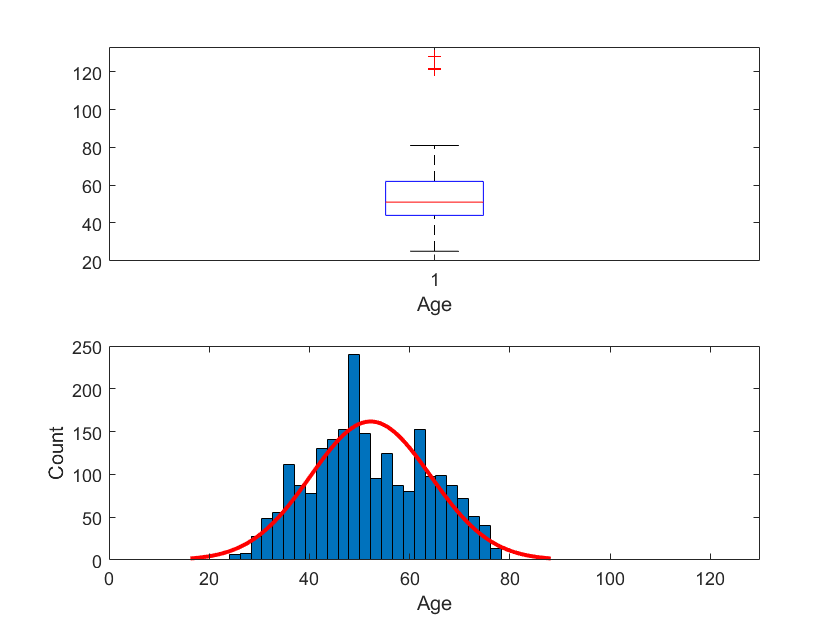

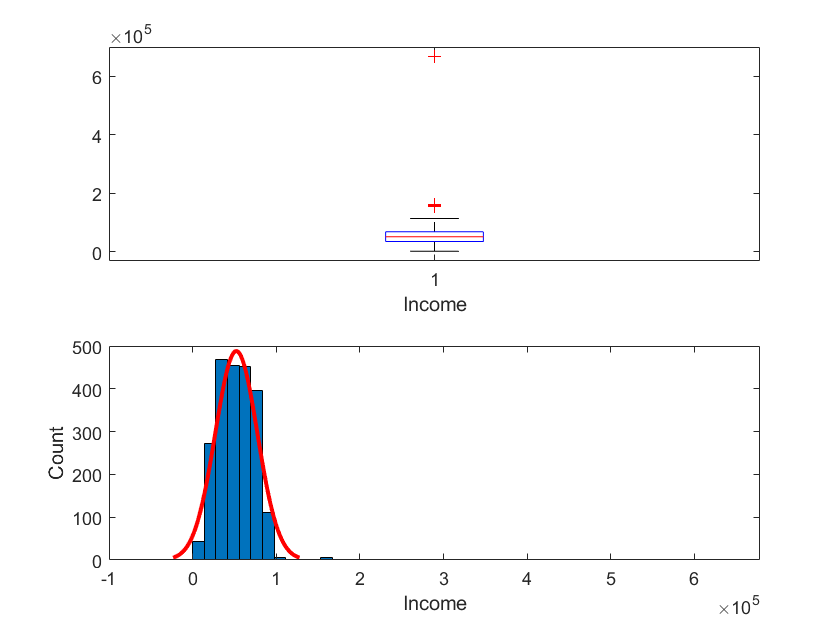

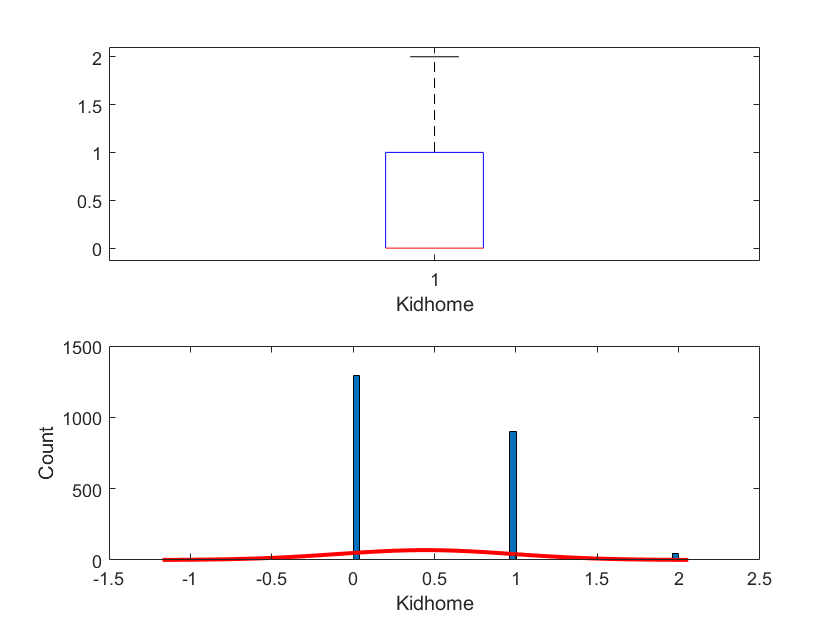

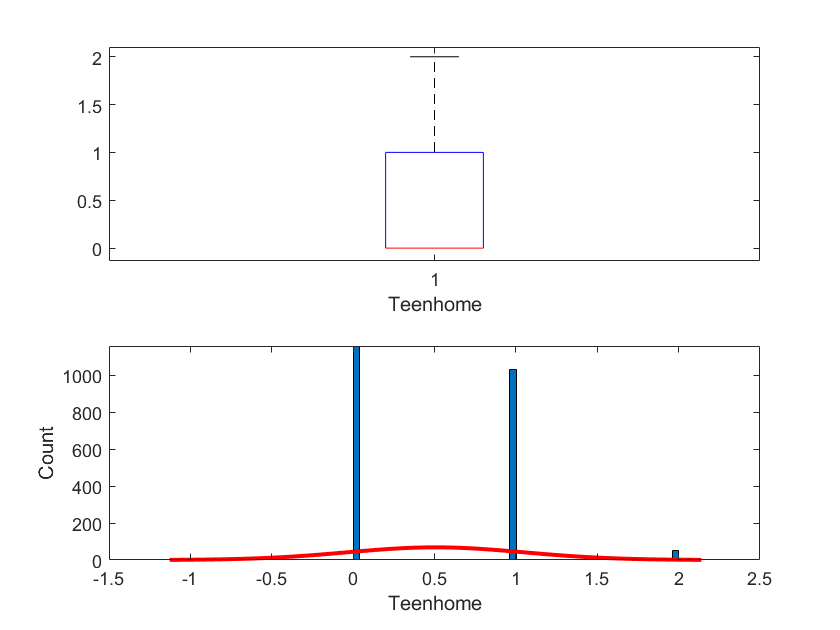

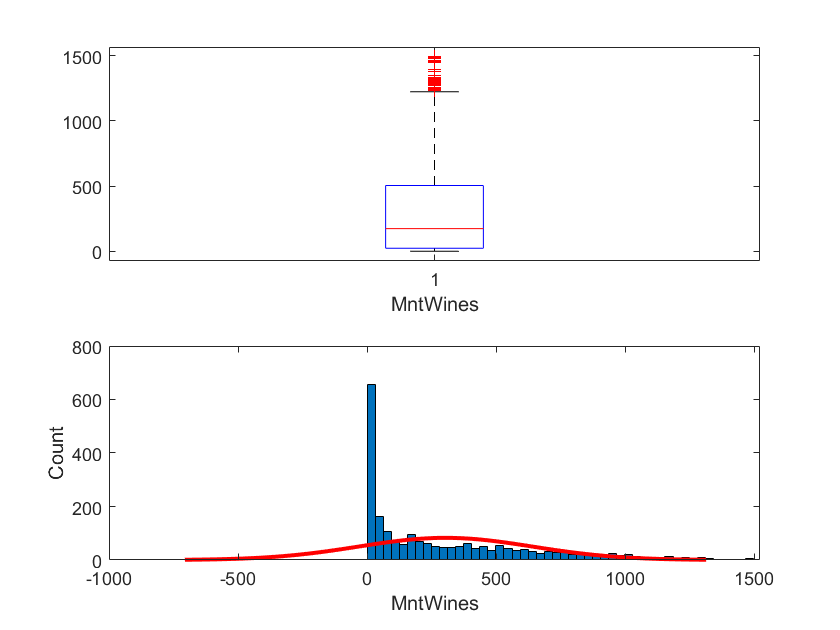

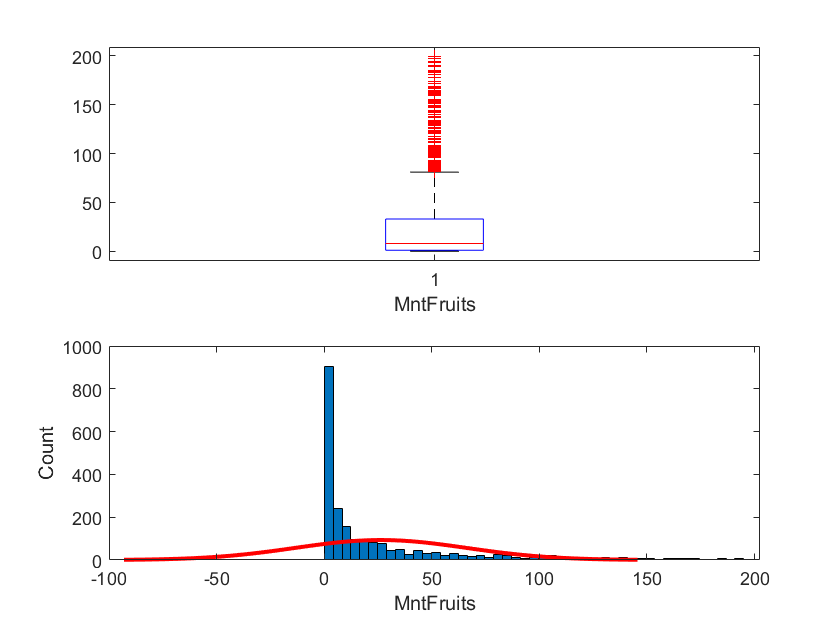

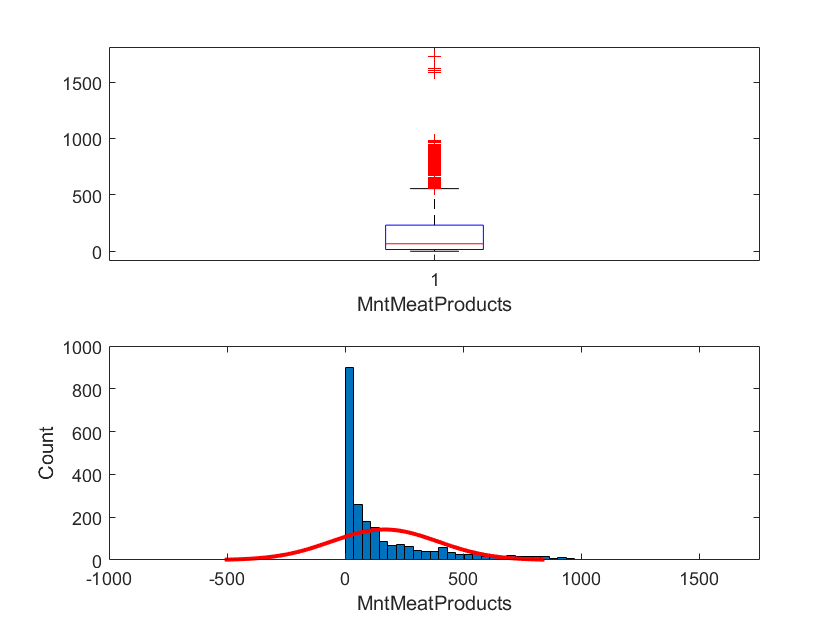

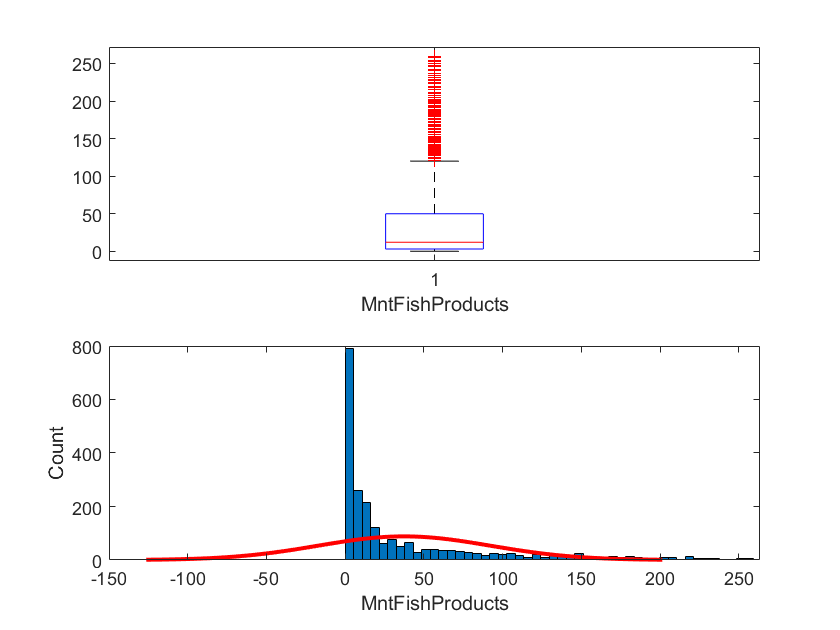

for c = (2:16)
    figure
    subplot(2,1,1)
    boxplot(marketing.(c));
    xlabel(marketing.Properties.VariableNames(c));
    subplot(2,1,2)
    histfit(marketing.(c));
    xlabel(marketing.Properties.VariableNames(c));
    ylabel('Count');
end

**Insight: **Có đa dạng kiểu khách hàng khác nhau:

- Những người có thu nhập cao như 700 nghìn thu nhập hàng năm và một số khách hàng có thu nhập hàng năm dưới 100 nghìn đô la là tốt. Tuy nhiên, phần lớn khách hàng có thu nhập hàng năm thấp và chỉ có một số ít có thu nhập trên $ 100k. Điều này có nghĩa là cửa hàng phục vụ chủ yếu khách hàng thuộc nhóm thu nhập thấp và không tiếp đãi khách hàng giàu có / sang trọng. Vì vậy, ta sẽ loại bỏ các ngoại lệ này nếu không nó sẽ gây ra vấn đề trong quá trình phân tích sâu hơn. 

- Đa số các khách hàng trong độ tuổi trung niên từ 40 - 65, một số ít trong độ tuổi 80 và hiếm người trên 120 tuổi. Như vậy độ tuổi khách hàng trọng tâm sẽ rơi vào 40-65, để tránh các vấn đề trong quá trình phân tích sau này, ta sẽ loại bỏ những khách hàng lớn hơn 120 tuổi.

% remove rows which have Income > 600000- it's outliers values
data = data(~(data.Income>600000),:);
marketingdata = marketingdata(~(marketingdata.Income>600000),:);
marketing = marketing(~(marketing.Income > 600000),:);
% remove rows which have Age > 120 - it's outliers values
data = data(~(data.Age > 120),:);
marketingdata = marketingdata(~(marketingdata.Age > 120),:);
marketing = marketing(~(marketing.Age >120),:);
% combine dataset with Education volumn
data = join(data,table(ID, Education));
disp(data);

     ID      Age      Income      Spending    Marital_Situation    hasChild    Education_years    Education 
    _____    ___    __________    ________    _________________    ________    _______________    __________

     1826    51          84835      1190          Alone              No               3           Graduation
        1    60          57091       577          Alone              No               3           Graduation
    10476    63          67267       251          In Couple          Yes              3           Graduation
     1386    54          32474        11          In Couple          Yes              3           Graduation
     5371    32          21474        91          Alone              Yes 

### Xử Lý Các Gía Trị NaN

Như đã thấy trước đó, biến **Income** có 24 giá trị NaN.

Qua tìm hiểu, nhóm em thấy có một số cách thường dùng để xử lý giá trị NaN như sau: 

- Xóa toàn bộ cột chứa giá trị NaN

- Xóa các hàng chứa giá trị NaN

- Áp dụng giá trị trung bình 

- Nhập giá trị trung bình của một tập hợp cụ thể: trong trường hợp này, chúng tôi sẽ phân chia theo bằng tốt nghiệp Giáo dục

- Sử dụng một mô hình để dự đoán các giá trị bị thiếu **K-Nearest Neighbor Imputation**

Trong bài này, nhóm em sử dụng cách xóa toàn bộ các hàng có chứa giá trị NaN.

% cách 1
data = data(~(isnan(data.Income)),:);
% cách 2
marketingdata = rmmissing(marketingdata);
marketing = rmmissing(marketing);
disp(size(marketingdata));

  Column 1

        2212

  Column 2

          29



disp(size(marketing));

  Column 1

        2212

  Column 2

          24



disp(size(data));

  Column 1

        2212

  Column 2

           8



Sau khi loại bỏ outliers và missing values thì được bảng dữ liệu** data, marketingdata, marketing** gồm có 2212 dòng .

### Tổng Quan Thống Kê

%statistical overview
marketing = removevars(marketing,{'ID'});
Mean = [] ; Median = [] ; Std = [] ; Var = [] ;Cov = []; Min  = [];Max = [];
for c = (1:15)
    Mean(c) = mean(marketing.(c));
    Median(c) = median(marketing.(c));
    Std(c) = std(marketing.(c));
    Var(c) = var(marketing.(c));
    Cov(c) = cov(marketing.(c));
    Min(c) = min(marketing.(c));
    Max(c) = max(marketing.(c));
end
names = strings;
for c = (1:15)
    names(c) = marketing.Properties.VariableNames(c);
end
result = table(transpose(Mean),transpose(Median),transpose(Std),transpose(Var),transpose(Cov),transpose(Min),transpose(Max),'VariableNames', ...
                {'Mean','Median','Std','Var','Cov','Min','Max'},'RowNames',transpose(names));
disp(result);

                  Mean      Median      Std         Var           Cov        Min        Max   
                 _______    ______    _______    __________    __________    ____    _________

    Age           52.086       51      11.702        136.93        136.93      25           81
    Income         51959    51371       21527    4.6342e+08    4.6342e+08    1730    1.624e+05
    Kidhome      0.44168        0     0.53695       0.28832       0.28832       0            2
    Teenhome     0.50588        0     0.54425       0.29621       0.29621       0            2
    MntWines      305.29    175.5      337.32    1.1379e+05    1.1379e+05       0         1493
    

### Phân Tích Cơ Bản

Tổng số lượng đăng ký mỗi năm trong biểu đồ hình cột sau

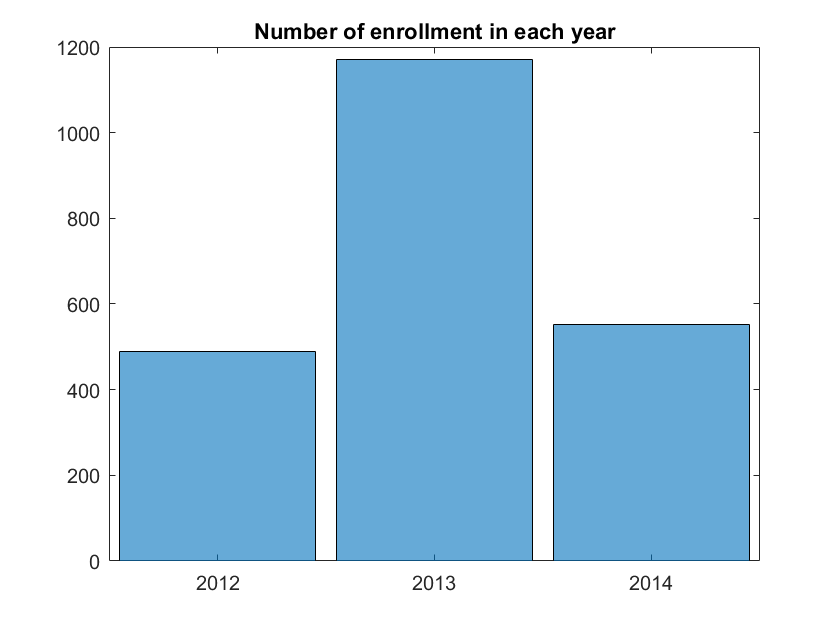

figure
histogram(categorical(year(marketingdata.Dt_Customer)));
title('Number of enrollment in each year');

Trong năm 2013, số lượng khách hàng đăng ký tăng mạnh so với năm 2012 và 2014. 

## **TRỰC QUAN HÓA DỮ LIỆU**

### Income

#### Mean and Median of Income in each country

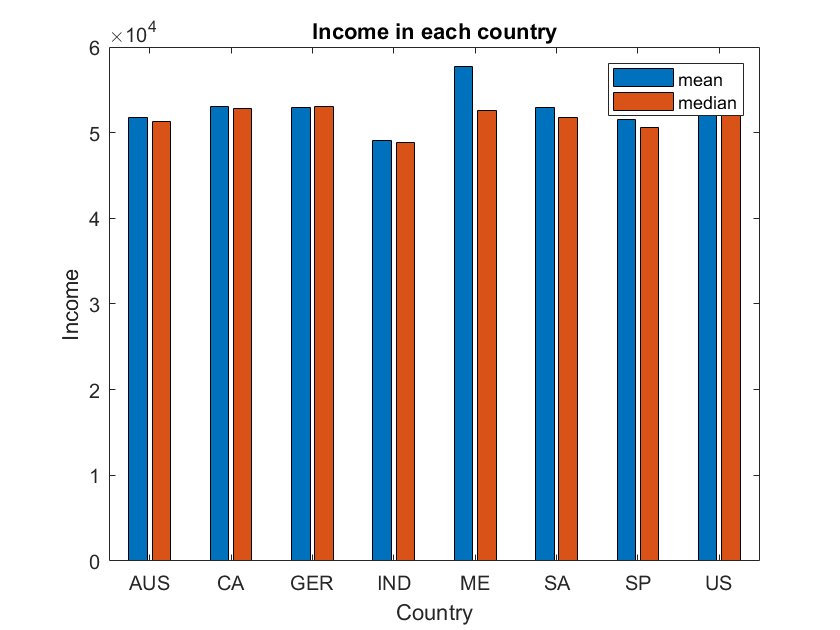

figure
x1 = varfun(@mean,marketingdata,"GroupingVariables","Country","InputVariables","Income");
x2 = varfun(@median,marketingdata,"GroupingVariables","Country","InputVariables","Income");
x = [x1.mean_Income x2.median_Income];
y = categorical({'AUS','CA','GER','IND','ME','SA','SP','US'});
y = reordercats(y,{'AUS','CA','GER','IND','ME','SA','SP','US'});
bar(y,x);
legend({'mean','median'});
title('Income in each country');
xlabel('Country');
ylabel('Income');

#### **Diploma distribution by income level**

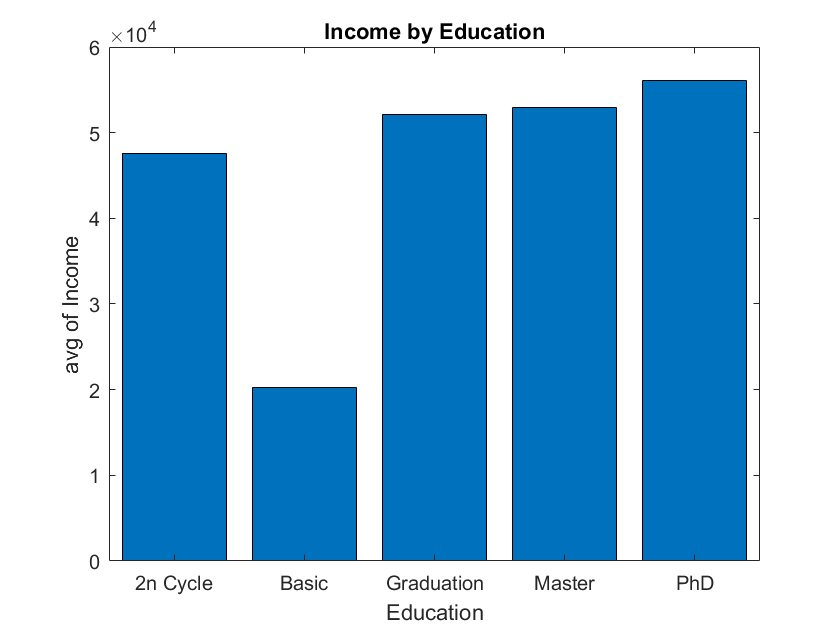

figure
a = varfun(@sum,data,"GroupingVariables","Education","InputVariables","Income");
b = a.sum_Income ./ a.GroupCount;
x = categorical({'2n Cycle','Basic','Graduation','Master','PhD'});
x = reordercats(x,{'2n Cycle','Basic','Graduation','Master','PhD'});
bar(x,b);
title('Income by Education');
xlabel('Education');
ylabel('avg of Income');

- Thu nhập trung bình là cao nhất là Tiến sĩ với 56161 dollars.

- Thu nhập trung bình thấp nhất là bằng cấp Cơ bản với 20306 dollars.

- Bằng cấp càng tốt, mức lương trung bình càng cao.

#### **Spending by Income**

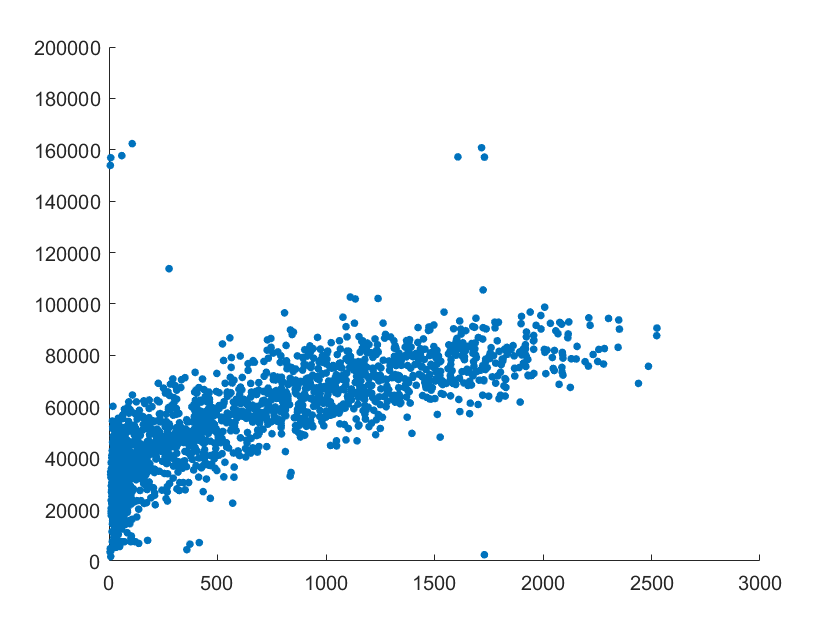

scatter(data.Spending,data.Income,15,'filled');
ylim([0 200000])
set(gca, 'YTickLabel', num2cell(get(gca, 'YTick')))

- Chi tiêu tỉ lệ thuận với mức thu nhập

#### Income level by parental status

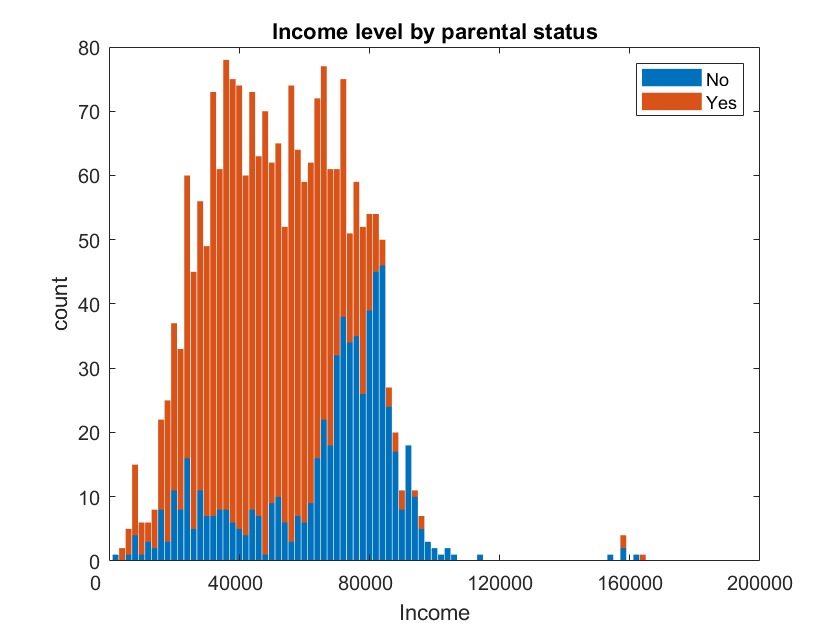

doc legend
Nochild=[];
for c = 1:length(data.Income)
    if isequal(data.hasChild(c),'No')       
        Nochild = [Nochild ;data.Income(c)];
    end
end
edge=0:2000:700000;
edge=[edge inf];
I = histcounts(data.Income,edge);
No = histcounts(Nochild,edge);
Yes=I-No;
figure
bar([No(:) Yes(:)],'stacked', 'BarWidth', 0.9);
xlim([0 100])
legend('No','Yes');
xt = get(gca, 'XTick');                                
set(gca, 'XTick', xt, 'XTickLabel', xt*2000);
ylabel('count');
xlabel('Income');
title('Income level by parental status');

- Những người có thu nhập cao chủ yêu là những người chưa có con.

- Những người có thu nhập thấp chủ yếu đã có ít nhất một con.

### **Diploma distribution by marital situation**

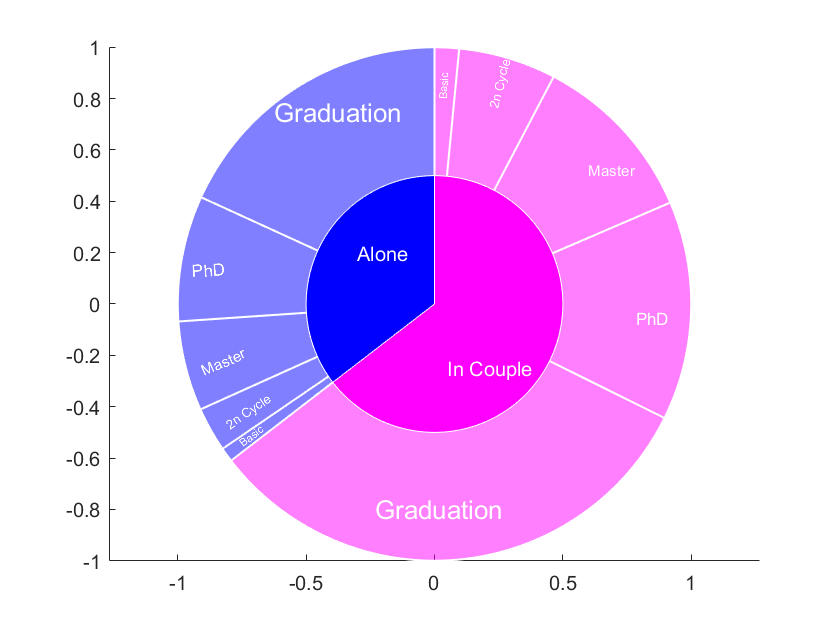

love=zeros(1,length(data.Marital_Situation));
X={'2n Cycle','Basic','Graduation','Master','PhD'};
for c=1:length(data.Marital_Situation)
    if isequal(data.Marital_Situation(c),'In Couple')
        love(c) = 1;
    end
end
nC1 = 0; Bas1 = 0; Gra1 = 0; Mas1 = 0; Ph1 = 0;
nC2 = 0; Bas2 = 0; Gra2 = 0; Mas2 = 0; Ph2 = 0;
for c=1:length(data.Education)  
    switch data.Education(c)
        case '2n Cycle'
        nC1 = nC1+love(c);
        nC2 = nC2+~love(c);
        case 'Basic'
        Bas1 = Bas1+love(c);
        Bas2 = Bas2+~love(c);
        case 'Graduation'
        Gra1 = Gra1+love(c);
        Gra2 = Gra2+~love(c);
        case 'Master'
        Mas1 = Mas1+love(c);
        Mas2 = Mas2+~love(c);
        case 'PhD'
        Ph1 = Ph1+love(c);
        Ph2 = Ph2+~love(c);
    end
end
couple = [nC1 Bas1 Gra1 Mas1 Ph1];
alone = [nC2 Bas2 Gra2 Mas2 Ph2];
[couple,s1]=sort(couple);
[alone,s2]=sort(alone);
al=sum(alone);
cp=sum(couple);
s=al+cp;
figure
hold on;
axis equal;
t=[0:0.001:1]*2*pi/s;
labels1=X(s1);
labels2=X(s2);
ang1 = t*cp;
ang2 = -t*al;
x1=0.5*sin(ang1);
y1=0.5*cos(ang1);
x2=0.5*sin(ang2);
y2=0.5*cos(ang2);
fill([0 2*x1],[0 2*y1],'m','FaceAlpha', 0.5);
fill([0 2*x2],[0 2*y2],'b','FaceAlpha', 0.5);
cyc = couple'*t;
ap=zeros(1,1001);
for c=1:5   
    h=text(-cyc(c,15)*10+0.5*(sin(ap(1001))+sin(cyc(c,1001)+ap(1001))),0.8*cos(ap(1001)+cyc(c,550)),labels1(c),'Color','w');
    if cyc(c,1001)-cyc(c,1)<pi/6
        set(h,'Rotation',abs(90-90/pi*(ap(1001)+cyc(c,1000))));
    end
    set(h,'fontsize', 5+couple(c)/90);
    ap=ap+cyc(c,:);
    plot([0 sin(ap) 0],[0 cos(ap) 0],'w','LineWidth',1);
    
end
tro = alone'*t;
bp=ap;
for c=1:5
    h=text(0.05+sin(bp(1001)+tro(c,350)),0.05+cos(bp(1001)+tro(c,300)),labels2(c),'Color','w');
    if tro(c,1001)-tro(c,1)<pi/6
        set(h,'Rotation',abs(270-180/pi*(bp(1001))));
    end
    set(h,'fontsize', 5+couple(c)/90);
    bp=bp+tro(c,:);
    plot([0 sin(bp) 0],[0 cos(bp) 0],'w','LineWidth',1);
end

fill([0 x1],[0 y1],'m','EdgeColor','w');
fill([0 x2],[0 y2],'b','EdgeColor','w');
text( 0.05,-0.25,'In Couple','Color','w');
text( -0.3,0.2,'Alone','Color','w');

- Sự phân bổ bằng cấp gần như là giống nhau ở cả hai nhóm Độc thân và Đã kết hôn.

### Purchases

"Tổng số lượng sản phẩm" : xác định tổng số sản phẩm mà mỗi khách hàng đã mua.

Xét tỷ lệ của số lượng lượt mua hàng trong mỗi kênh ('Giao dịch', 'Trang web', 'Danh mục', 'Cửa hàng') để xem hiệu suất của từng kênh:

- 39% tất cả các giao dịch mua là tại cửa hàng

-  27,5% trên web 

- 15,6% trong giao dịch 

- 17,9% theo danh mục.

Có thể kết luận rằng, từ dữ liệu, hơn một nửa số khách hàng đã mua hàng tại cửa hàng và trang web.

figure
sumDeal = sum(marketingdata.NumDealsPurchases);
sumWeb = sum(marketingdata.NumWebPurchases);
sumStore = sum(marketingdata.NumStorePurchases);
sumCatalog = sum(marketingdata.NumCatalogPurchases);
labels = {'Deal', 'Web','Store','Catalog'};
pie([sumDeal sumWeb sumStore sumCatalog],labels);
title({'Purchases in each channel'});

- NumStorePurchases :     38.959479

- NumWebPurchases  :     27.484906

- NumCatalogPurchases  :    17.911748

- NumDealsPurchases :     15.643868

Tiếp theo, xét tổng số lần mua ở mỗi quốc gia. Có thể thấy rằng, hầu hết khách hàng đến từ Tây Ban Nha

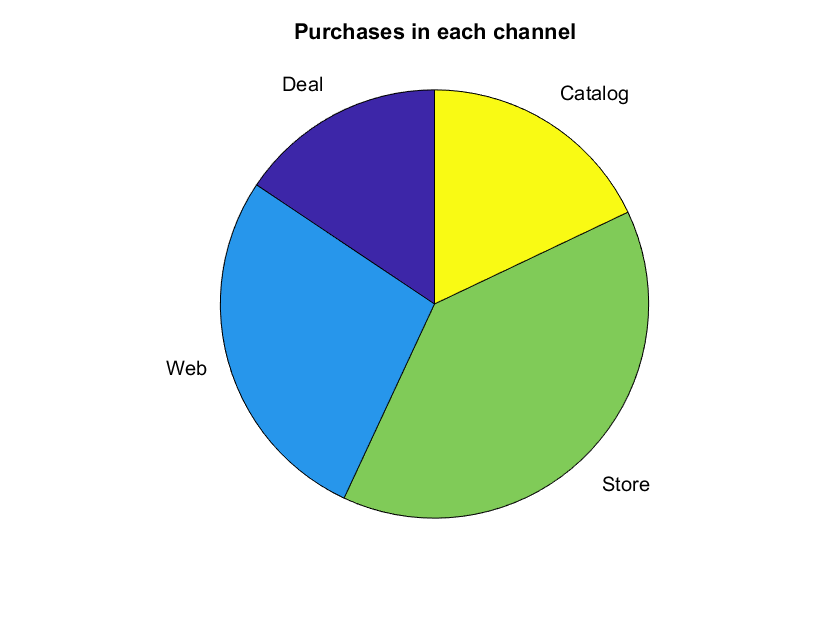

figure
y = categorical({'AUS','CA','GER','IND','ME','SA','SP','US'});
y = reordercats(y,{'AUS','CA','GER','IND','ME','SA','SP','US'});
t = varfun(@sum,marketingdata,"GroupingVariables","Country","InputVariables",{'NumCatalogPurchases','NumStorePurchases','NumDealsPurchases','NumWebPurchases'});
total = t.sum_NumCatalogPurchases+t.sum_NumStorePurchases+t.sum_NumDealsPurchases+t.sum_NumWebPurchases;
bar(y,total);
legend('sum');
title('Total purchases in each country');

xlabel('Country');

### Products

 Xét Tỷ lệ tổng thể của các sản phẩm đã mua. Có thể thấy rằng, 50,2% tất cả các sản phẩm được mua bởi tất cả các khách hàng là rượu và vị trí thứ hai (27,6%) là thịt.

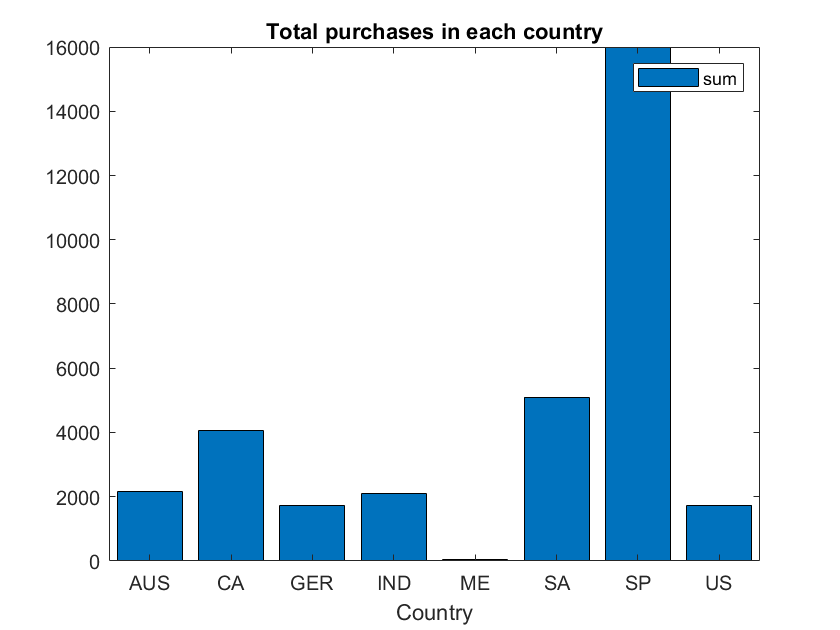

figure
sumWine = sum(marketingdata.MntWines);
sumFruit = sum(marketingdata.MntFruits);
sumMeat = sum(marketingdata.MntMeatProducts);
sumFish = sum(marketingdata.MntFishProducts);
sumSweet = sum(marketingdata.MntSweetProducts);
sumGold = sum(marketingdata.MntGoldProds);
labels = {'Wine','Fruit','Meat','Fish','Sweet','Gold'};
pie([sumWine sumFruit sumMeat sumFish sumSweet sumGold],labels);

title({'Overall %Products'});

- `MntWines        :    50.171114 `

- `MntMeatProducts :   27.558681 `

- `MntGoldProds    :    7.266755 `

- `MntFishProducts :     6.194380 `

- `MntSweetProducts:    4.467320 `

- `MntFruits       :    4.341748`

Xét hành vi mua hàng trung bình của từng khách hàng. Xét Tỷ lệ trung bình của mỗi sản phẩm được mua bởi một ID(một khách hàng) .

Từ 100% tất cả sản phẩm mà mỗi người mua, thấy rằng:

- 45,8% là rượu

- 24,95% sản phẩm thịt

- 12% sản phẩm vàng

- 7% sản phẩm cá

- 5% đồ ngọt

- 4,9% sản phẩm trái cây.

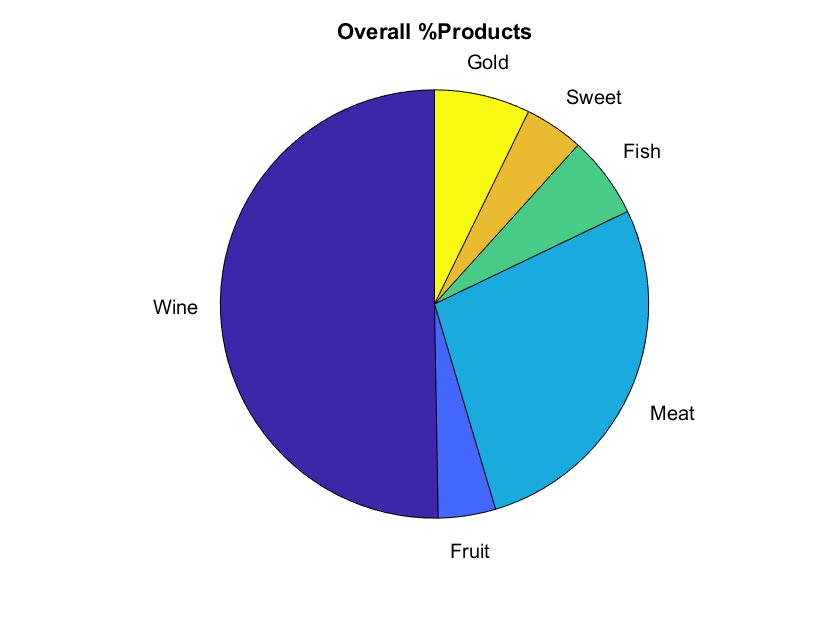

t = marketingdata.MntWines + marketingdata.MntFruits + marketingdata.MntMeatProducts+marketingdata.MntFishProducts+marketingdata.MntSweetProducts+marketingdata.MntGoldProds ;
t1 = sum(marketingdata.MntWines ./ t *100);
t2 = sum(marketingdata.MntFruits ./ t*100);
t3 = sum(marketingdata.MntMeatProducts ./t *100);
t4 = sum(marketingdata.MntFishProducts ./t *100);
t5 = sum(marketingdata.MntSweetProducts ./t *100);
t6 = sum(marketingdata.MntGoldProds ./t *100);
labels = {'Wine','Fruit','Meat','Fish','Sweet','Gold'};
pie([t1 t2 t3 t4 t5 t6],labels);
title({'Average Product for each ID'});

- `MntWines         :   45.848136 `

- `MntMeatProducts  :  24.950802 `

- `MntGoldProds     :  12.019649 `

- `MntFishProducts  :   7.153233 `

- `MntSweetProducts :   5.077723 `

- `MntFruits        :   4.950457 `

### Campaign

Tính hiệu suất của từng chiến dịch đã tiến hành. Dưới đây, biểu đồ tròn và biểu đồ thanh ngang hiển thị số lượng chấp nhận và tỷ lệ thành công trong mỗi chiến dịch. 

Có thể thấy rằng, chiến dịch số 2 có thể gặp một số vấn đề vì nó rất ít được chấp nhận trong khi các chiến dịch khác được chấp nhận với tỷ lệ tương tự.

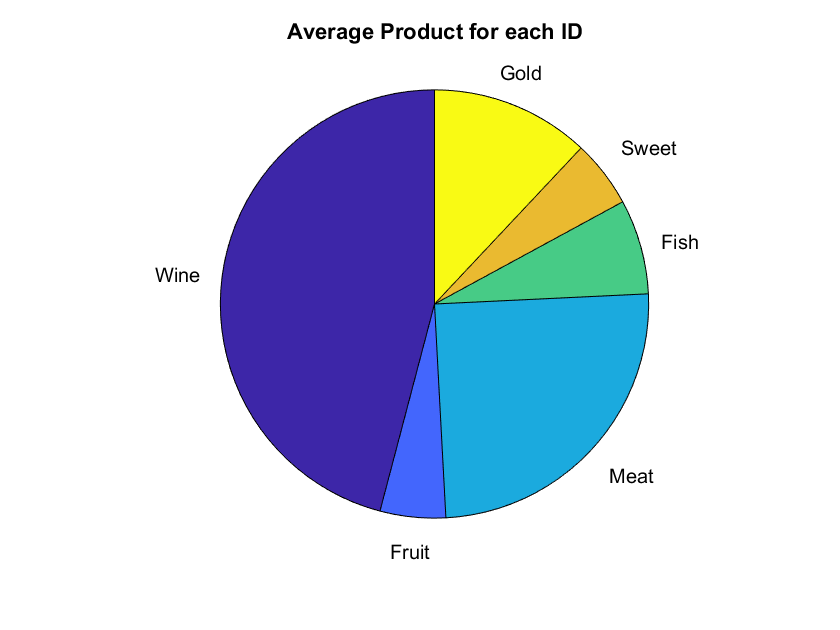

figure
sumCp1 = sum(marketingdata.AcceptedCmp1);
sumCp2 = sum(marketingdata.AcceptedCmp2);
sumCp3 = sum(marketingdata.AcceptedCmp3);
sumCp4 = sum(marketingdata.AcceptedCmp4);
sumCp5 = sum(marketingdata.AcceptedCmp5);
sumcp = [sumCp1 sumCp2 sumCp3 sumCp4 sumCp5];
labels = {'Cp1','Cp2','Cp3','Cp4','Cp5'};
pie(sumcp,labels);
title({'Overall each campaign of successfull rate '});

figure()
barh(sumcp,'r');
yticklabels({'Campaign1' ,'Campaign2', 'Campaign3' ,'Campaign4',' Campaign5'});
title('Success');

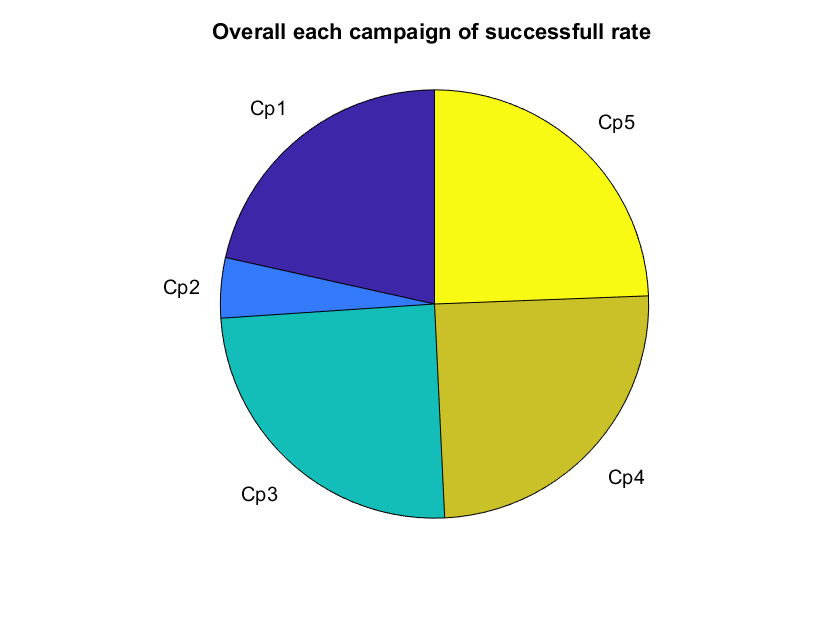

figure()
t = varfun(@sum,marketingdata,"GroupingVariables","Country","InputVariables",{'AcceptedCmp1','AcceptedCmp2','AcceptedCmp4','AcceptedCmp3','AcceptedCmp5'});
avg1 = t.sum_AcceptedCmp1 ./ t.GroupCount * 100;
avg2 = t.sum_AcceptedCmp2 ./ t.GroupCount * 100;
avg3 = t.sum_AcceptedCmp3 ./ t.GroupCount * 100;
avg4 = t.sum_AcceptedCmp4 ./ t.GroupCount * 100;

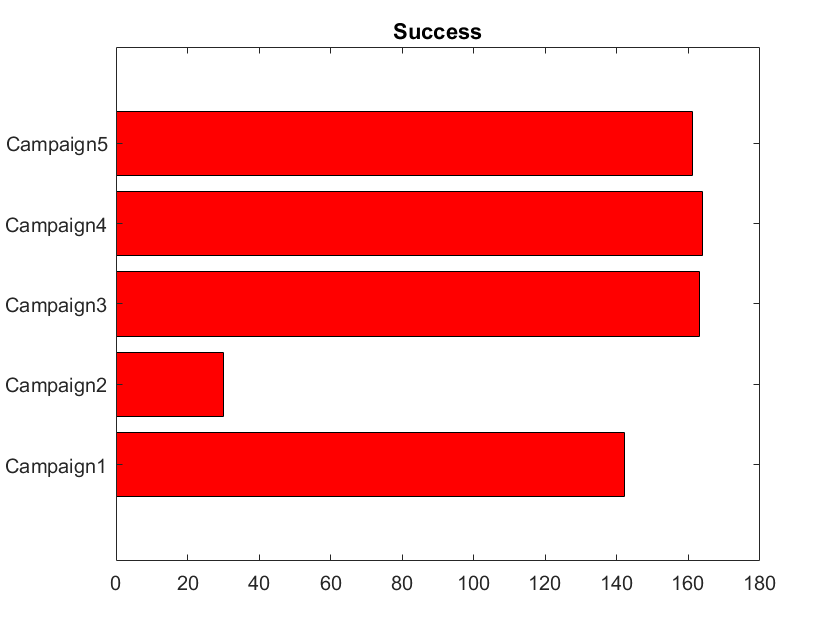

avg5 = t.sum_AcceptedCmp5 ./ t.GroupCount * 100;
avg = [avg1 avg2 avg3 avg4 avg5];
y = categorical({'AUS','CA','GER','IND','ME','SA','SP','US'});
y = reordercats(y,{'AUS','CA','GER','IND','ME','SA','SP','US'});
bar(y,avg);

legend({'Cp1','Cp2','Cp3','Cp4','Cp5'})
title('average performance of each campaign in each country');
xlabel('Country');
ylabel('Rate');

## KIỂM TRA GIẢ THUYẾT THỐNG KÊ

**Kiểm định giả thiết thống kê về các vấn đề như sau:**

- Có sự khác biệt về trung bình lương của người có bằng Tiến sĩ và trung bình lương của người có bằng Thạc sĩ hay không?

- Mối tương quan  giữa thu nhập hằng năm và số tiền chi tiêu có thật sự có ý nghĩa thống kê hay không?

- Mối tương quan giữa bằng cấp đại học và tình trạng hôn nhân có thật sự có ý nghĩa thống kê hay không?

### Kiểm tra phân phối chuẩn 

Trước khi thực hiện kiểm định giả thiết thống kê, chúng ta phải biết được chúng ta sẽ sử dụng phương pháp thống kê nào. Phương pháp thống kê chia thành hai phần

- Phương pháp thống kê tham số

- Phương pháp thống kê phi tham số

Việc đầu tiên là kiểm tra dữ liệu cần kiểm định có tuân theo phân phối chuẩn hay không?

Nếu tuân theo phân phối chuẩn thì sử dụng phương pháp thống kê tham số. Ngược lại, nếu dữ liệu không tuân theo phân phối chuẩn thì sử dụng phương pháp thống kê phi tham số.

**Có hai cách để kiểm tra xem dữ liệu có tuân theo phân phối chuẩn hay không**

- Phương pháp biểu đồ:

                     Biểu đồ phân bố tần suất (Histogram plot)

                     Biểu đồ xác suất chuẩn (QQ plot)

         2. Phương pháp thống kê:

                    Shapiro test    

                    D'Agostino and Pearson test

                    Anderson-Darling test    

                    Kolmogorvo-Smirnov Test

Kiểm định Shapiro-Wilk với x như sau:

Giá trị của thống kê là:


$$W=\frac{{\left(\sum_{i=1}^n a_i x_i \right)}^2 }{\sum_{i=1}^n {\left(x_i -\bar{x} \right)}^2 }$$


Trong đó: $x_i \;$là giá trị thứ i nhỏ nhất của x

                                                                                      $a_i$ là hằng số Shapiro-Wilk

                                                                                      $\bar{x} \;$ là trung bình mẫu

#### Độ tuổi (Age)

- Sử dụng biểu đồ

figure()
subplot(1, 2, 1)
histogram(data.Age);
histfit(data.Age);
title('Histogram of Age')
subplot(1, 2, 2)
qqplot(data.Age);

- Kiểm định giả thiết thống kê

$H_0 :$ "Biến độ tuổi tuân theo phân phối chuẩn"

$H_1$:  "Biến độ tuổi không tuân theo phân phối chuẩn"

[H, pValue, W] = swtest(data.Age, 0.05);

$\textrm{pValue}<0\ldotp 05\Longrightarrow$Bác bỏ $H_0$. Biến độ tuổi không tuân theo phân phối chuẩn với độ tin cậy 95%

#### Thu nhập (Income)

- Sử dụng biểu đồ

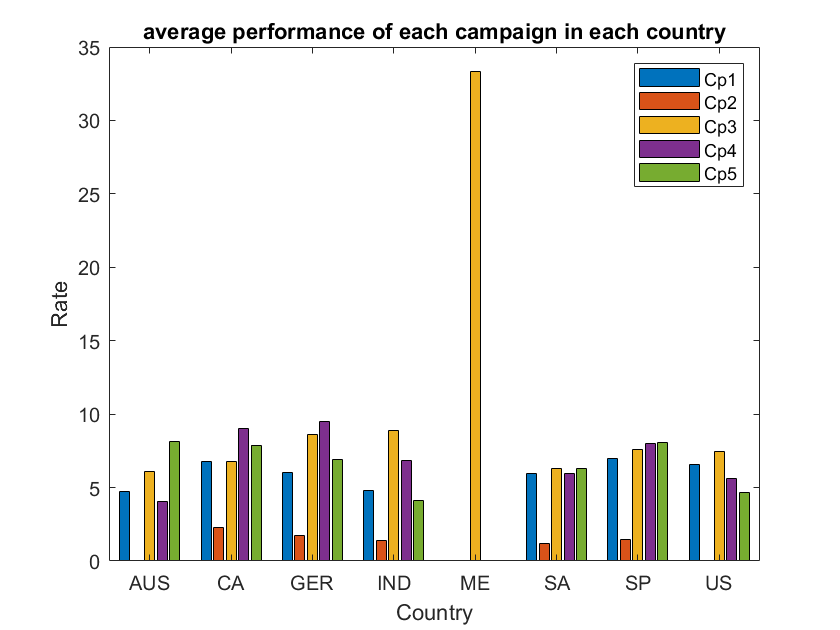

figure()
subplot(1, 2, 1)
histogram(marketingdata.Income)
histfit(marketingdata.Income)

title('Histogram of Income');
subplot(1, 2, 2)
qqplot(marketingdata.Income)

Kiểm định Anderson-Darling:

Giá trị của thống kê:


$$\textrm{AD}=-n-\frac{1}{n}\;\sum_{i=1}^n \left(2i-1\right)\left\lbrack \textrm{lnF}\left(x_i \right)+\ln \left(1-F\left(x_{n-i+1} \right)\right)\right\rbrack$$


                                    Trong đó: $F\left(x_i \right)\;$là hàm phân phối tích lũy của biến cần phân tích.

                                                    $i^{\textrm{th}}$ là giá trị nhỏ thứ i.

- Kiểm định giả thiết thống kê 

$H_0 :$ "Biến thu nhập tuân theo phân phối chuẩn"

$H_1$:  "Biến thu nhập không tuân theo phân phối chuẩn"

[H, p] = adtest(marketingdata.Income);

$\textrm{pValue}<0\ldotp 05\Longrightarrow \;$Bác bỏ $H_0$. Biến độ thu nhập không tuân theo phân phối chuẩn với độ tin cậy 95%

#### Tiêu thụ (Spending)

- Sử dụng biểu đồ

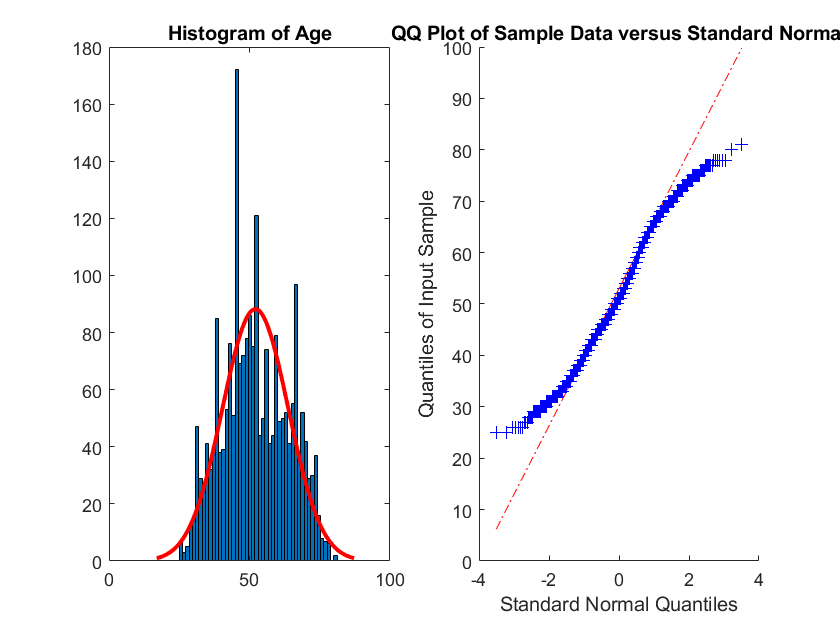

figure()
subplot(1, 2, 1)
histogram(data.Spending);
histfit(data.Spending);
title('Histogram of spending')
subplot(1, 2, 2)

qqplot(data.Spending);

- Kiểm định giả thiết thống kê

$H_0 :$ "Biến tiêu thụ tuân theo phân phối chuẩn"

$H_1$:  "Biến tiêu thụ không tuân theo phân phối chuẩn"

[H, pValue, W] = swtest(data.Spending, 0.05);

$\textrm{pValue}<0\ldotp 05\Longrightarrow \;$Bác bỏ  Biến tiêu thụ không tuân theo phân phối chuẩn với độ tin cậy 95%

### Rank Significant Tests

**Kiểm định Mann-Whitney's**

Thống kê Mann-Whitney:


$$U=n_1 n_2 +\frac{n_2 \left(n_{2\;} +1\right)}{2}-\sum_{i=n_1 \;+1}^{n_2 } R_i$$


                                                                           Trong đó: $n_1$ là cỡ mẫu 1

                                                                                           $n_2$ là cỡ mẫu 2

                                                                                          $R_i$ là hạng của cỡ mẫu

Có sự khác biệt về trung bình lương của người có bằng Tiến sĩ và trung bình lương của người có bằng Thạc sĩ hay không?

PhD_graduate = marketingdata((marketingdata.Education == "PhD"),:);
Master_graduate = marketingdata((marketingdata.Education == "Master"),:);
Graduation_graduate = marketingdata((marketingdata.Education == "Graduation"),:);
Basic_graduate = marketingdata((marketingdata.Education == "Basic"),:);
Second_Cycle_graduate = marketingdata((marketingdata.Education == "2c Cycle"),:);

Với mức ý nghĩa 5%, kiểm định thu nhập của tiến sĩ có tuân theo phân phối chuẩn?

$H_0 :$ "Biến thu nhập của tiến sĩ tuân theo phân phối chuẩn"

$H_1$:  "Biến thu nhập của tiến sĩ không tuân theo phân phối chuẩn"

[H, pValue, W] = swtest(PhD_graduate.Income, 0.05);

Với mức ý nghĩa 5%, kiểm định thu nhập của thạc sĩ có tuân theo phân phối chuẩn?

$H_0 :$ "Biến thu nhập của thạc sĩ tuân theo phân phối chuẩn"

$H_1$:  "Biến thu nhập của thạc sĩ không tuân theo phân phối chuẩn"

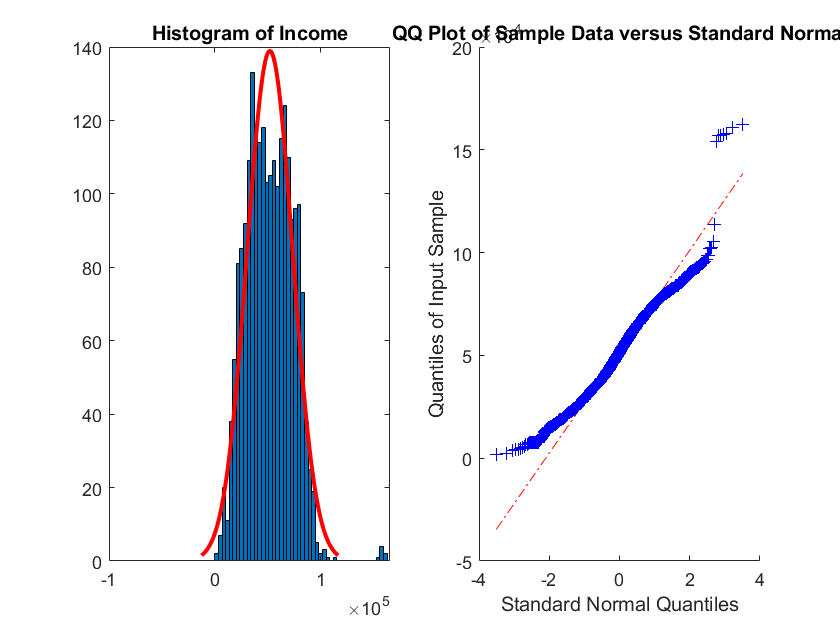

[H, pValue, W] = swtest(Master_graduate.Income, 0.05);

Với mức ý nghĩa  = 5%, thu nhập trung bình của người có bằng tiến sĩ có khác gì so với thu nhập trung bình của người có bằng thạc sĩ không?

$H_0$: "Thu nhập trung bình của tiến sĩ không khác so với thạc sĩ"

$H_1$: "Thu nhập trung bình của tiến sĩ khác so với thạc sĩ"

format compact

summary(PhD_graduate);

summary(Master_graduate);

p = ranksum(PhD_graduate.Income, Master_graduate.Income);

Với mức ý nghĩa 5%, có sự khác nhau về lượt mua trung bình của người dân ở Tây Ban Nha so với các nước khác không?

$H_0$: "Lượt mua trung bình của người dân ở Tây Ban Nha không khác so với người dân các nước khác"

$H_1$: "Lượt mua trung bình của người dân ở Tây Ban Nha khác so với người dân các nước khác"

marketingdata.PurchasesMade = (marketingdata.NumCatalogPurchases + marketingdata.NumDealsPurchases + marketingdata.NumStorePurchases + marketingdata.NumWebPurchases);
SP = marketingdata((marketingdata.Country == "SP"), :);
Other = marketingdata((marketingdata.Country ~= "SP"), :);
[h, p] = ttest2(SP.PurchasesMade, Other.PurchasesMade);

$p>0\ldotp 05\Longrightarrow$ Không có cơ sở bác bỏ $H_0$. Không có sự khác nhau giữa lượt mua trung bình của người dân ở Tây Ban Nha so với các nước còn lại.

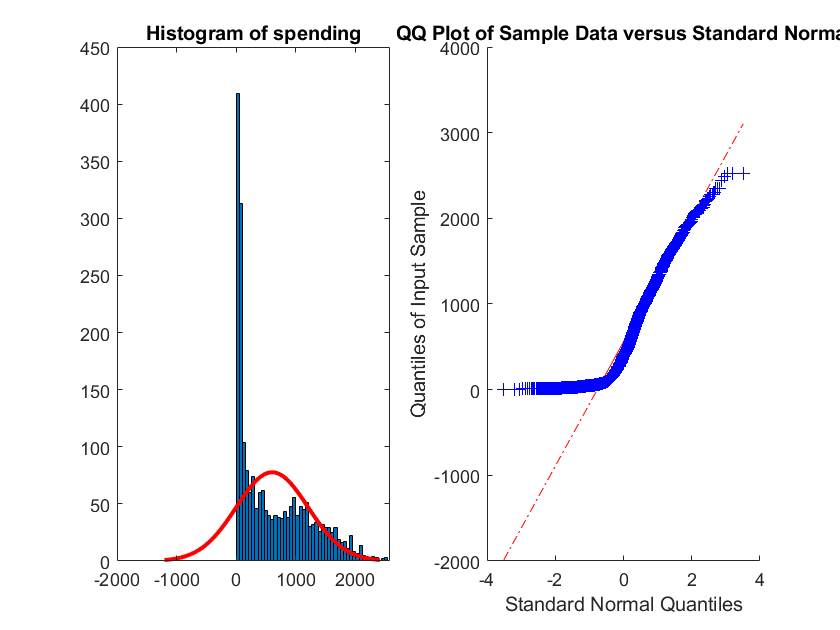

figure()
mdl = fitlm(marketingdata.MntGoldProds, marketingdata.NumStorePurchases);

plot(mdl);

ME = marketingdata((marketingdata.Country == "ME"), :);

ResponseME = ME((ME.Response == 1), :);

### **Kiểm tra tương quan**

#### **Các biến số: Kiểm tra hệ số tương quan Spearman**

    **Công thức sau được sử dụng để tính toán hệ số tương quan Spearman:**


$$r_s = 1 - \frac{6 \Sigma D^2}{n(n^2 - 1)}$$


$r_s
$ = Hệ số tương quan Spearman

$D
$ = Chênh lệch bậc của các biến tương ứng

$n$ = Số mẫu

Tương quan thứ hạng Spearman là một kiểm tra phi tham số được sử dụng để đo mức độ liên kết giữa hai biến.

Câu hỏi thứ hai là tìm xem liệu có mối tương quan có ý nghĩa thống kê giữa thu nhập và số tiền chi tiêu hay không.

**1. Phát biểu giả thuyết**

* $H_0$: Không có mối liên hệ đơn điệu nào giữa thu nhập và số tiền chi tiêu

* $H_a$: Có sự liên kết đơn điệu giữa thu nhập và số tiền chi tiêu

**2. Lập kế hoạch phân tích**

* ***Mức ý nghĩa***: Kiểm định giả thuyết ở mức ý nghĩa 5%

* ***Phương pháp kiểm tra***: Sử dụng kiểm tra tương quan Spearman để xác định xem hai biến có tương quan hay không. Phương pháp thống kê này định lượng mức độ mà các biến đang xem xét được liên kết bởi một hàm đơn điệu, nghĩa là một mối quan hệ tăng hoặc giảm. Là một kiểm định giả thuyết thống kê, phương pháp này giả định rằng các mẫu không tương quan với nhau (không loại bỏ được $H_0$).

Do đó, nếu giả thiết của chúng ta là đúng, thì kết quả của phép thử sẽ cho phép bác bỏ giả thuyết không.

[RHO,PVAL] = corr(data.Spending, data.Income,'Type','Spearman');
txt = sprintf('Kiểm tra tương quan Spearman không tham số: Hệ số tương quan: %.4f, p-value: %.4f',[RHO,PVAL]);
disp(txt)

Rs càng gần +1 hoặc -1, thì mối tương quan có thể càng mạnh. Tương quan dương hoàn hảo là +1 và tương quan âm hoàn hảo là -1. Giá trị $r_s$ là 0,8525 cho thấy một mối quan hệ tích cực khá mạnh.

Hệ số tương quan cao tạo ra mối quan hệ tích cực mạnh mẽ giữa hai biến, xác nhận giả thuyết thay thế.

#### **Các biến phân loại: Kiểm định Chi bình phương cho tính độc lập**

Câu hỏi thứ ba của chúng tôi là tìm xem liệu có mối tương quan có ý nghĩa thống kê giữa bằng tốt nghiệp và tình hình hôn nhân hay không.

**1. Phát biểu giả thuyết**

* $H_0$ *: Giáo dục và Tình trạng hôn nhân là độc lập

* $H_a$ *: Giáo dục và Tình trạng hôn nhân không độc lập

**2. Lập kế hoạch phân tích**

**** Mức ý nghĩa***: Kiểm tra giả thuyết ở mức ý nghĩa 5%

* ***Phương pháp kiểm tra***: Sử dụng kiểm định Chi bình phương về tính độc lập để xác định liệu có mối quan hệ đáng kể giữa hai biến phân loại hay không.

[table,chi2,p, labels] = crosstab(data.Education,data.Marital_Situation);
disp(table)

**Bậc tự do**

Tính toán bậc tự do là chìa khóa để hiểu tầm quan trọng của thống kê Chi bình phương và tính hợp lệ của giả thuyết không.

**Bậc tự do được cho bởi công thức:**


$$dof = (r-1)(c-1)$$


Trong đó $r,c
$ lần lượt là số giá trị của $2$ biến phân loại.

[r, c] = size(table);
dof = (r - 1)*(c - 1)

**Thống kê thử nghiệm là một biến ngẫu nhiên Chi bình phương **$(X^2)$** được xác định bởi phương trình sau:**


$$X_c^2 = \Sigma \frac{(O_i - E_i)^2}{E_i}$$


Trong đó:

$O_r$ là tần số đếm được quan sát ở mức $r$ của biến $A$ và mức $c$ của biến $B$

$E_r$ là tần số đếm kì vọng ở mức $r$ của biến $A$ và mức $c$ của biến $B$

significance = 0.05;
critical = chi2inv(1-significance,dof);
fprintf('probability=%.3f, critical=%.3f, stat=%.3f',[1-significance, critical, chi2])
if abs(chi2) >= critical
    fprintf('Dependent (We reject H0)')
else
    fprintf('Independent (We fail to reject H0)')

Variables:
    ID: 481×1 double
        Values:
            Min           13  
            Median      5441  
            Max        11181  
    Year_Birth: 481×1 double
        Values:
            Min         1899  
            Median      1967  
            Max         1991  
    Education: 481×1 cell array of character vectors
    Marital_Status: 481×1 cell array of character vectors
    Income: 481×1 double
        Values:
            Min            4023
            Median        55212
            Max       1.624e+05
    Kidhome: 481×1 double
        Values:
            Min          0    
            Median       0    
            Max          2    
    Teenhome: 481×1 double
        Values:
            Min          0    
            Median       1    
            Max          2    
    Dt_Customer: 481×1 datetime
        Values:
            Min   

end

**P-value:**

P-value là xác suất quan sát một thống kê mẫu mà cực giống thống kê thử nghiệm. Vì thống kê thử nghiệm là Chi bình phương, chúng ta nên sử dụng bảng Chi bình phương để đánh giá xác suất liên quan đến thống kê thử nghiệm bằng cách sử dụng bậc tự do mà chúng ta đã tìm thấy ở trên.

fprintf('significance=%.3f, p=%.3f',[significance,p]);

Variables:
    ID: 365×1 double
        Values:
            Min            9  
            Median      5300  
            Max        11178  
    Year_Birth: 365×1 double
        Values:
            Min         1943  
            Median      1968  
            Max         1992  
    Education: 365×1 cell array of character vectors
    Marital_Status: 365×1 cell array of character vectors
    Income: 365×1 double
        Values:
            Min             6560
            Median         50943
            Max       1.5773e+05
    Kidhome: 365×1 double
        Values:
            Min          0    
            Median       0    
            Max          2    
    Teenhome: 365×1 double
        Values:
            Min          0    
            Median       1    
            Max          2    
    Dt_Customer: 365×1 datetime
        Values:
            Min

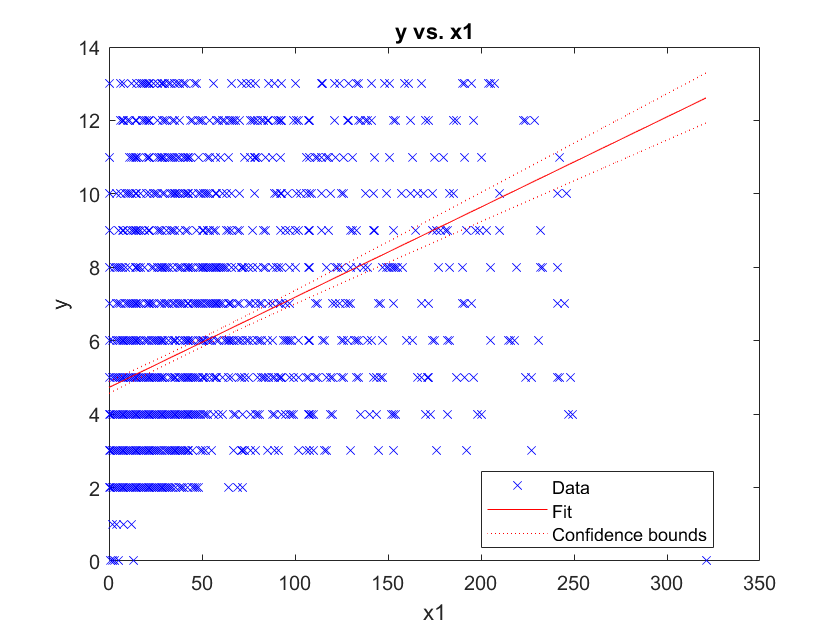

Kiểm tra tương quan Spearman không tham số: Hệ số tương quan: 0.8525, p-value: 0.0000


    64   136
    20    34
   402   713
   125   240
   175   306


dof = 4

probability=0.950, critical=9.488, stat=1.689

Independent (We fail to reject H0)

significance=0.050, p=0.793

Independent (We fail to reject H0)

if p <= significance
	fprintf('Dependent (We reject H0)');
else
	fprintf('Independent (We fail to reject H0)');
end

**Giải thích kết quả:**

Chúng ta có thể giải thích kết quả theo hai cách:

* P-value cao hơn mức ý nghĩa 5%, chúng ta không bác bỏ giả thuyết vô hiệu.

* Thống kê thử nghiệm thấp hơn giá trị tới hạn, chúng ta không thể bác bỏ giả thuyết không.

Chúng ta có thể kết luận rằng tình trạng hôn nhân độc lập với bằng tốt nghiệp sở hữu ở mức độ tin cậy 95%.